### Define periphery and core regions of nucleoid

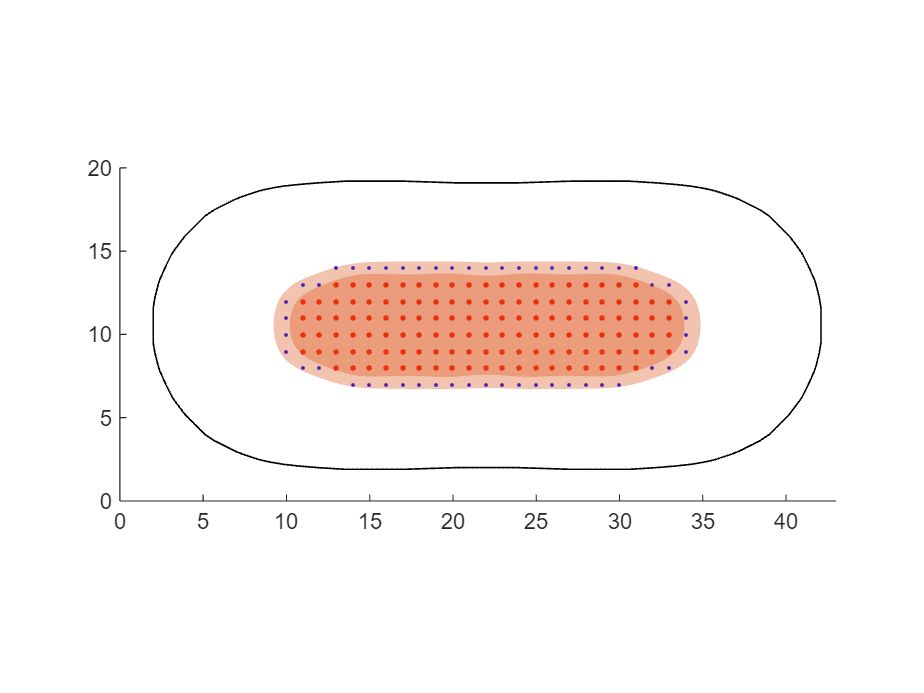

[coord_in_core, coord_in_peri, peri1, peri2] =...
    Nuc_Seg(spMap, [cntr_low+0.05,cntr_low],...
    cell_outline, num_pix_y, aspt_ratio, ["off" "on"]);


[Step_in_Core,~] =...
    Extract_Step_InRegion(raw_spatialDisp,...
    coord_in_core,num_pix_y,aspt_ratio);
[Step_in_Core_simu,~] =...
    Extract_Step_InRegion(Simu_spatialDisp,...
    coord_in_core,num_pix_y,aspt_ratio);

[Step_in_Peri,~] =...
    Extract_Step_InRegion(raw_spatialDisp,...
    coord_in_peri,num_pix_y,aspt_ratio);
[Step_in_Peri_simu,~] =...
    Extract_Step_InRegion(Simu_spatialDisp,...
    coord_in_peri,num_pix_y,aspt_ratio);

% weight ratio of periphery and core
[pop_peri_ratio,pop_core_ratio] = Pop_Peri_Core_Ratio(...
    5e5,acc_fit,Ro,Lo,anchor_spMap,scaling_width,...
    scaling_length,num_pix_y,aspt_ratio,{peri1,peri2});

## Nucloeid periphery viscosity

fprintf('\n========  Nucleoid Periphery Viscosity  ========\n');


========  Nucleoid Periphery Viscosity  ========


pop_peri_ratio

pop_peri_ratio = 0.0625

slack_d=0.2

slack_d = 0.2000

slack_acc=0.1

slack_acc = 0.1000

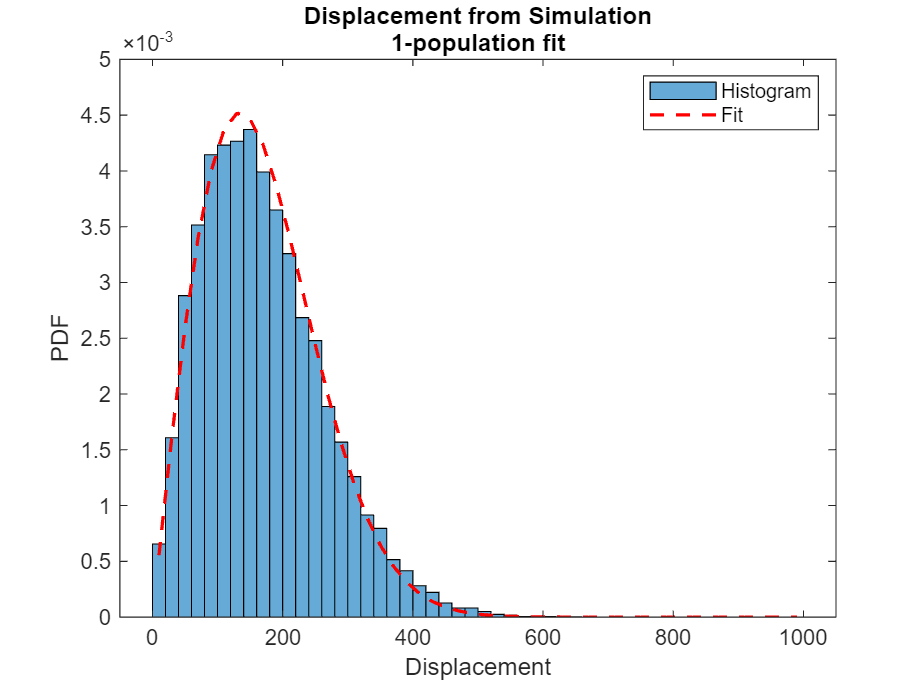


[p_simu_peri,p_fit_peri,simu_result_peri,exp_result_peri,f1,f2] =...
    In_Nuc_fit(Step_in_Peri_simu,Step_in_Peri,...
    pop_peri_ratio,slack_d,slack_acc);

SaveFigure(result_folder,'Periphery fit from simulation',...
    f1, {'fig','png','svg'},[])

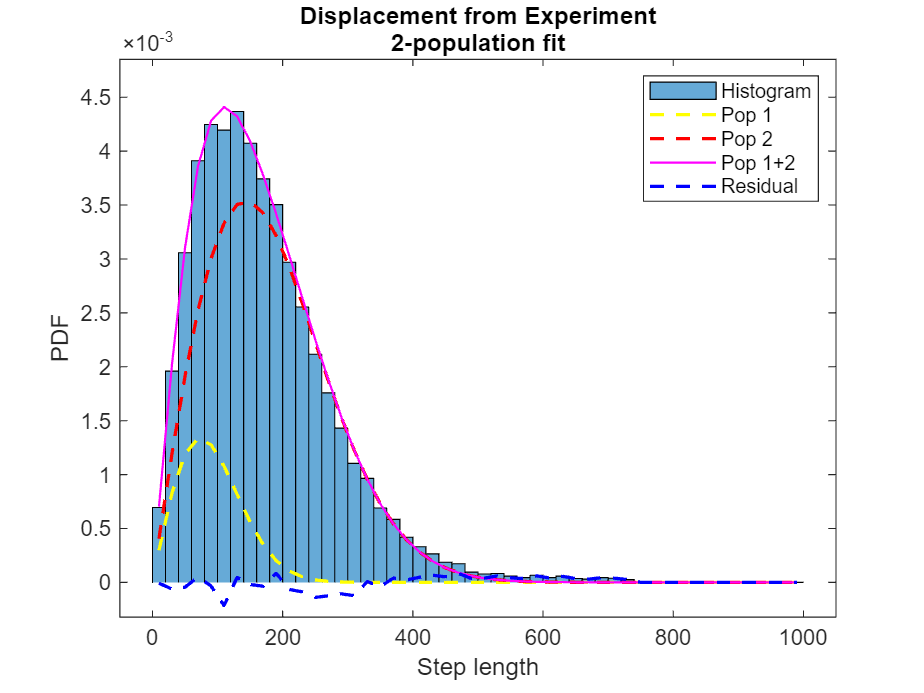

SaveFigure(result_folder,'Periphery fit from experiment',...
    f2, {'fig','png','svg'},[])


p_peri_fit_ci = In_Nuc_fit_ci(Step_in_Peri,p_fit_peri);

%  Comparison with inputs / 1-population result
shift_peri = struct( ...
    'InputPeriRatio' , pop_peri_ratio      , ...
    'FitPeriRatio'   , p_fit_peri(1)           , ...
    'delta_PeriRatio', abs(p_fit_peri(1)-pop_peri_ratio) , ...
    'a_simulation'   , p_simu_peri(1)          , ...
    'a_fit'          , p_fit_peri(4)           , ...
    'delta_a_peri'   , abs(p_fit_peri(4)-p_simu_peri(1))/p_simu_peri(1));

% Physical properties derived from the fit
Diff_peri_um2s = p_fit_peri(2) / (4*delta_t) * 1e-3;            % µm²/s
Vis_peri    = 1.380649e-23*temp_K / (6*pi*probe_radius* ...
                   Diff_peri_um2s * 1e-12) * 1e3;          % cP
Vis_peri_lb = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_peri_fit_ci(2)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)
Vis_peri_ub = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_peri_fit_ci(1)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)

Viscosity_peri = struct(...
    'Periphery_outline', peri1,...
    'PeriRatio',         pop_peri_ratio,...
    'Fitting_tolerance', [slack_d,slack_acc],...
    'DiffCoeff_um2_s',  Diff_peri_um2s,...
    'PeriVis',          Vis_peri,...
    'PeriVis_lb',       Vis_peri_lb,...
    'PeriVis_ub',       Vis_peri_ub);

fprintf('\n-----------  Physical Properties  -----------\n');


-----------  Physical Properties  -----------


fprintf('D_periphery  (µm²/s)           : %.3e\n', Diff_peri_um2s);

D_periphery  (µm²/s)           : 6.753e-02


fprintf('Nucleoid Periphery Viscosity (cP)  : %.2f\n',   Vis_peri);

Nucleoid Periphery Viscosity (cP)  : 262.92


fprintf('----------------------------------------------\n');

----------------------------------------------


## Nucloeid core viscosity

fprintf('\n==========  Nucleoid Core Viscosity  ==========\n');


==========  Nucleoid Core Viscosity  ==========


pop_core_ratio

pop_core_ratio = 0.1398

slack_d=0.2

slack_d = 0.2000

slack_acc=0.1

slack_acc = 0.1000

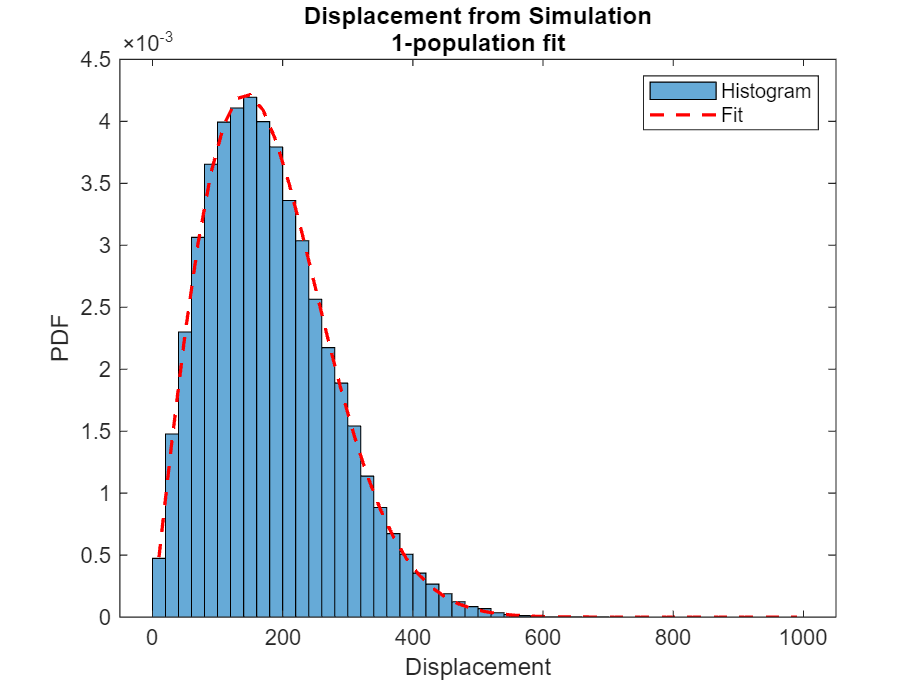


[p_simu_core,p_fit_core,...
    simu_result_core,exp_result_core,f1,f2] =...
    In_Nuc_fit(Step_in_Core_simu,Step_in_Core,...
    pop_core_ratio,slack_d,slack_acc);

SaveFigure(result_folder,'Core fit from simulation',...
    f1, {'fig','png','svg'},[])

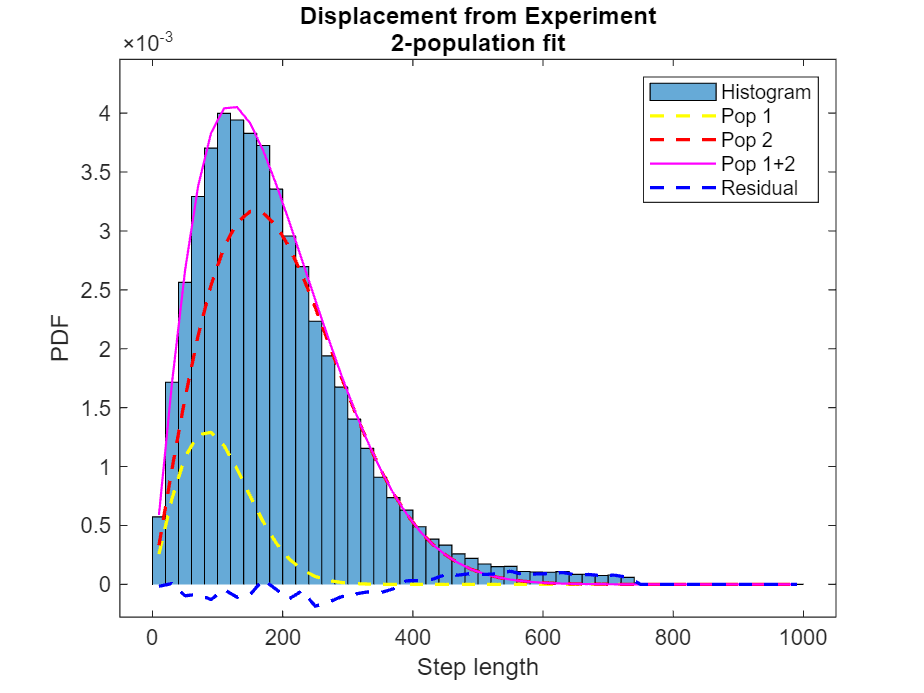

SaveFigure(result_folder,'Core fit from experiment',...
    f2, {'fig','png','svg'},[])


p_core_fit_ci = In_Nuc_fit_ci(Step_in_Core,p_fit_core);

%  Comparison with inputs / 1-population result
shift_core = struct( ...
    'InputCoreRatio' , pop_core_ratio      , ...
    'FitCoreRatio'   , p_fit_core(1)           , ...
    'delta_coreRatio', abs(p_fit_core(1)-pop_core_ratio) , ...
    'a_simulation'   , p_simu_core(1)          , ...
    'a_fit'          , p_fit_core(4)           , ...
    'delta_a_core'   , abs(p_fit_core(4)-p_simu_core(1))/p_simu_core(1));

% Physical properties derived from the fit
Diff_core_um2s = p_fit_core(2) / (4*delta_t) * 1e-3;            % µm²/s
Vis_core    = 1.380649e-23*temp_K / (6*pi*probe_radius* ...
                   Diff_core_um2s * 1e-12) * 1e3;          % cP
Vis_core_lb = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_core_fit_ci(2)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)
Vis_core_ub = 1.380649e-23*temp_K/(6*pi*probe_radius*(p_core_fit_ci(1)/(4*delta_t)*1e-3)*1e-12)*1e3; %cP (centipoise, mPa⋅s)

Viscosity_core = struct(...
    'Core_outline',      peri2,...
    'CoreRatio',         pop_core_ratio,...
    'Fitting_tolerance', [slack_d,slack_acc],...
    'DiffCoeff_um2_s', Diff_core_um2s,...
    'CoreVis',          Vis_core,...
    'CoreVis_lb',       Vis_core_lb,...
    'CoreVis_ub',       Vis_core_ub);

fprintf('\n-----------  Physical Properties  -----------\n');


-----------  Physical Properties  -----------


fprintf('D_core  (µm²/s)           : %.3e\n', Diff_core_um2s);

D_core  (µm²/s)           : 8.541e-02


fprintf('Nucleoid Core Viscosity (cP)  : %.2f\n',   Vis_core);

Nucleoid Core Viscosity (cP)  : 207.89


fprintf('----------------------------------------------\n');

----------------------------------------------


Save results

clear f1 f2  slack_d slack_acc
clear peri1 peri2 pop_peri_ratio pop_core_ratio
clear Diff_peri_um2s Vis_peri Vis_peri_ub Vis_peri_lb
clear Diff_core_um2s Vis_core Vis_core_lb Vis_core_ub
clear Step_in_Core Step_in_Core_simu 
clear Step_in_Peri Step_in_Peri_simu
clear p_fit_core p_fit_peri p_core_fit_ci p_peri_fit_ci
clear p_simu_core p_simu_peri
clear simu_result_core simu_result_peri
clear exp_result_core exp_result_peri
clear coord_in_peri coord_in_core

Constants = struct(...
    'FrameInterval',     delta_t,...
    'Temperature',       temp_K,...
    'ProbeRadius',       probe_radius);

save(fullfile(result_folder,'VisPeriCore.mat'), ...
    'Constants', ...
    'Viscosity_peri', ...
    'Viscosity_core', ...
    'shift_peri', ...
    'shift_core', ...
    '-v7');             % v7.3 for large file
clear Constants Viscosity_peri Viscosity_core shift_peri shift_core
fprintf('\n Nucleoid Periphery and Core Viscosities saved to %s\n', fullfile(result_folder,'VisPeriCore.mat'));


 Nucleoid Periphery and Core Viscosities saved to L:\MIGRATED\Lab_Members\Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\Dataset\LAM022_24h_NanocageTracking_withHeater\Result_2026_02_12\VisPeriCore.mat
